## Data preprocessing

clc;
close all;
clear variables;

### Loading files

input_file_subfolder = 'data/raw';
intput_file_expension = 'bmp';

input_files = dir(input_file_subfolder + "/" +  "*." + intput_file_expension)

input_files = 600×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


### Example file

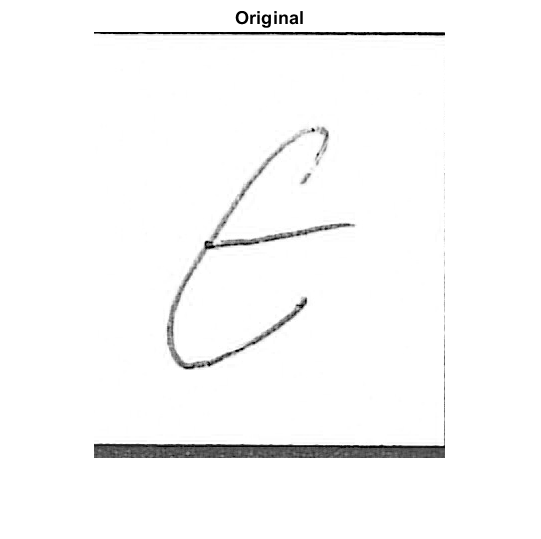

input_file = input_files(121);
file_path = input_file.folder + "\" + input_file.name;
img = imread(file_path);
figure()
imshow(img)
title('Original')

### Preprocessing example

tic
[img_cropped, img_binary] = edge_removal(img);
toc 

Elapsed time is 0.018650 seconds.


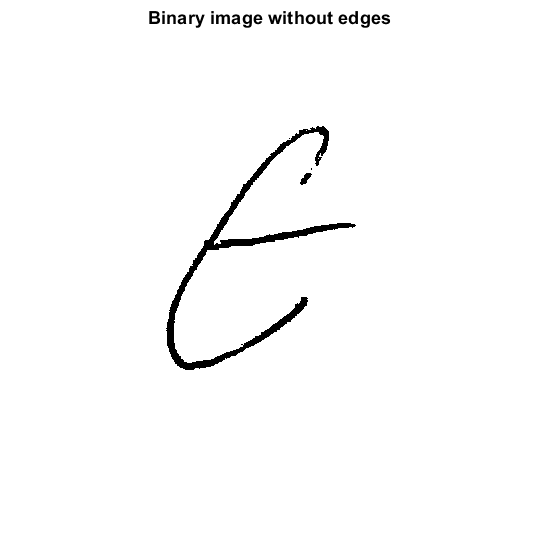


figure()
imshow(img_binary)
title('Binary image without edges')

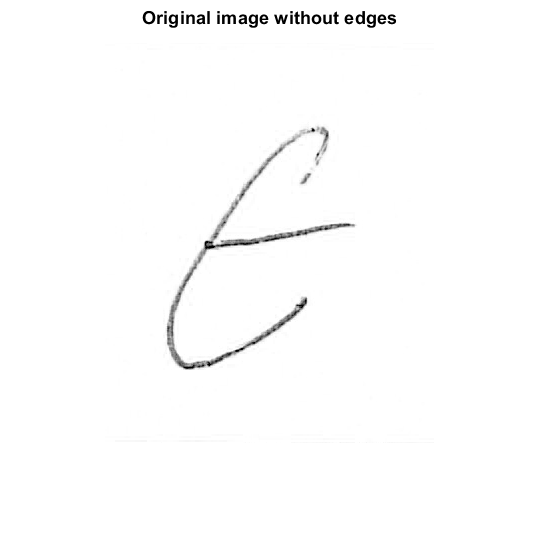


figure()
imshow(img_cropped)
title('Original image without edges')

### Preprocessing

#### Determining dimensions

dim1_array = zeros(length(input_files), 1);
dim2_array = zeros(length(input_files), 1);

for i = 1:length(input_files)
    input_file_path = input_files(i).folder + "\" + input_files(i).name;
    
    img = imread(input_file_path);
    
    dim1_array(i) = size(img, 1);
    dim2_array(i) = size(img, 2);
end

median_dim1 = prctile(dim1_array, 50)

median_dim1 = 419

median_dim2 = prctile(dim2_array, 50)

median_dim2 = 361

#### Preprocess all

output_subfolder_binarized = 'data\preprocessed\binarized';
output_subfolder_grayscale = 'data\preprocessed\grayscale';
tic
for input_file = input_files'
    
    input_file_path = input_file.folder + "\" + input_file.name;
    

Edge removal

    
    img = imresize(imread(input_file_path),[median_dim1, median_dim2]);
    [img_cropped, img_binary] = edge_removal(img);

#### Save images

    output_file_path_binary = output_subfolder_binarized + "\" + input_file.name;
    imwrite(img_binary, output_file_path_binary)
    
    output_file_path_grayscale = output_subfolder_grayscale + "\" + input_file.name;
    imwrite(img_cropped, output_file_path_grayscale)
end
toc

Elapsed time is 21.553106 seconds.
